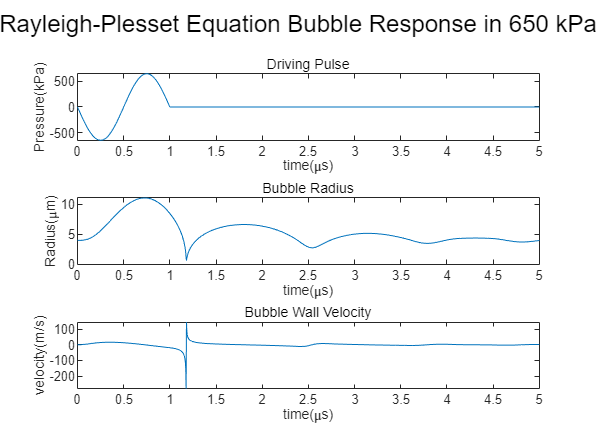


clearvars
%% Acoustic Parameter
run('Acoustic_Param.m');


%% Rayleigh-Plesset-Marmottant model ode45 solver

tspan = [0 :4E-9:5*10^-6];
%tspan = [0 5*10^-6];
[t,R] = ode45(@(t,R) marmottant_equ_update(t,R,f,cycle,d_p,T,phase,R0),tspan,[R0;0]); % time 1 mm

Rt = R(:,1); % Radius
bub_veloc = R(:,2);  % Bubble Wall Veloc


%% Plot Bubble Radius Curve

Rasp = d_p*sin(2*pi*f*t'+phase); % Applied Acoustic Force
for i = 1 : length(t)
    
    if t(i,1) > T * cycle
       Rasp(1,i) = 0;
    end
end


figure;

subplot(311)
plot(t*10^6,(Rasp)*10^-3)
xlabel('time(\mus)');
ylabel('Pressure(kPa)');
title('Driving Pulse')

subplot(312)
plot(t*10^6,Rt*10^6);
xlabel('time(\mus)');
ylabel('Radius(\mum)');
title('Bubble Radius')

subplot(313)
plot(t*10^6,bub_veloc);
title('Bubble Wall Velocity')
xlabel('time(\mus)');
ylabel('velocity(m/s)');

sgtitle(sprintf('Rayleigh-Plesset Equation Bubble Response in %d kPa', d_p/10^3))

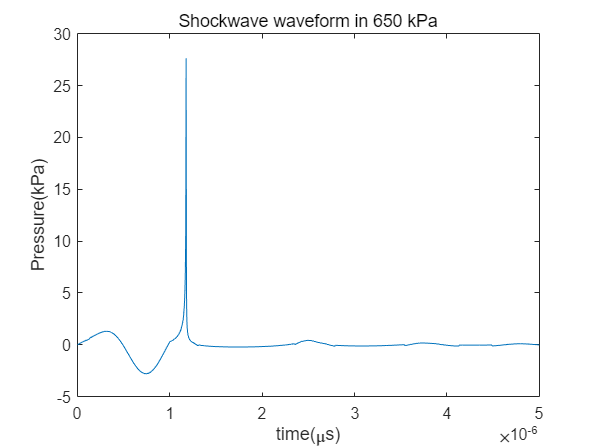


%% Radius to Pressure
p_r = Rasp;
run('Radius_to_Pressure_Param.m');
r = 3*10^-3; % 3mm distance from the center of cavity
sw_p = density * (Rt.^2.*R_a + 2*Rt.*bub_veloc.^2)/r; % Acoustic Emission Calculation equation8
%% Plot Derived Pressure Waveform  
figure;
plot(t,sw_p*10^-3)
xlabel('time(\mus)');
ylabel('Pressure(kPa)');
title('Shockwave waveform');
title(sprintf('Shockwave waveform in %d kPa', d_p/10^3))


%define the grid
Nx = 600;%600
Ny = 450;%450
dx = 2e-4;%2e-4
dy = 2e-4;%2e-4
Kgrid = kWaveGrid(Nx,dx,Ny,dy);
c = 1500;
%Kgrid.setTime

%Use point per wavelength ppl to reduce dx until stable
%dx = 2e-4 ppl = 37500
ppw = 40000;
wavelength = 1.5/120*Nx;
dx_new = wavelength/ppw

dx_new = 1.8750e-04

w = 1500/1e6%1.5mm

w = 0.0015

p = wavelength/dx

p = 37500


%define the medium prperty
medium.sound_speed = 1500;
medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;

% create the time array
%Kgrid.makeTime(medium.sound_speed,0.3,6e-5);%128SQRT2/1500
Kgrid.t_array = 0:4e-9:6e-5;
%t_array_new = Kgrid.t_array(1:126)
% create the time array explicitly
%Kgrid.t_array = t;
deltaT = zeros(485,1);

% define a single source point
source.p_mask = zeros(Nx, Ny);
%source.p_mask(70/120*Nx, Ny/2) = 1;
source.p_mask(70/120*Nx+50, Ny/2+50) = 1;
source.p_mask(70/120*Nx+50, Ny/2-50) = 1;
source.p_mask(70/120*Nx-50, Ny/2+50) = 1;
source.p_mask(70/120*Nx-50, Ny/2-50) = 1;

% define a time varying sinusoidal source
% source_freq = 1e6;   % [Hz]
% source_mag = 3;         % [Pa]
%source.p = source_mag * sin(2 * pi * source_freq * t_array_new);
source.p = sw_p'/1000

source = 包含以下字段的 struct :
    p_mask: [600×450 double]
         p: [-1.0614e-16 0.0217 0.0432 0.0646 0.0857 0.1065 0.1270 0.1473 0.1672 0.1868 0.2060 0.2249 0.2434 0.2615 0.2792 0.2966 0.3137 0.3303 0.3466 0.3626 0.3782 0.3935 0.4085 0.4232 0.4375 0.4515 0.4652 0.4786 0.4917 0.5045 0.5171 0.5294 0.5414 … ]



% filter the source to remove high frequencies not supported by the grid
%source.p = filterTimeSeries(Kgrid, medium, source.p);

%define the sensor in a line
x_offset = 20/120*Nx % [grid points]

x_offset = 100

width = 50/90*Ny% [grid points]

width = 250

sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2) = 1;

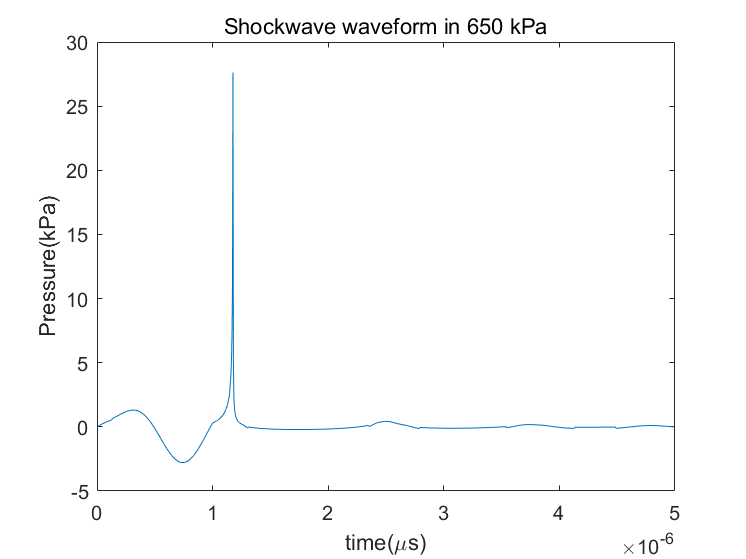


figure;
plot(t,sw_p*10^-3)
xlabel('time(\mus)');
ylabel('Pressure(kPa)');
title('Shockwave waveform');
title(sprintf('Shockwave waveform in %d kPa', d_p/10^3))

Running k-Wave simulation...
  start time: 21-Jul-2023 17:35:18
  reference sound speed: 1500m/s
  dt: 4ns, t_end: 60us, time steps: 15001
  input grid size: 600 by 450 grid points (120 by 90mm)
  maximum supported frequency: 3.75MHz
  precomputation completed in 0.21493s
  starting time loop...
  estimated simulation time 9min 15.037s...


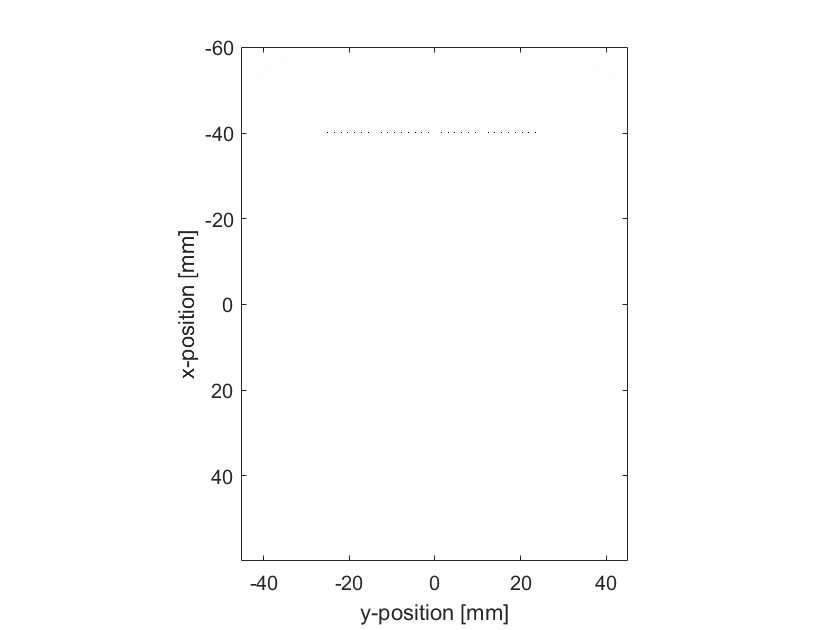

  simulation completed in 7min 55.5053s
  total computation time 7min 55.753s




% run the simulation
sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);

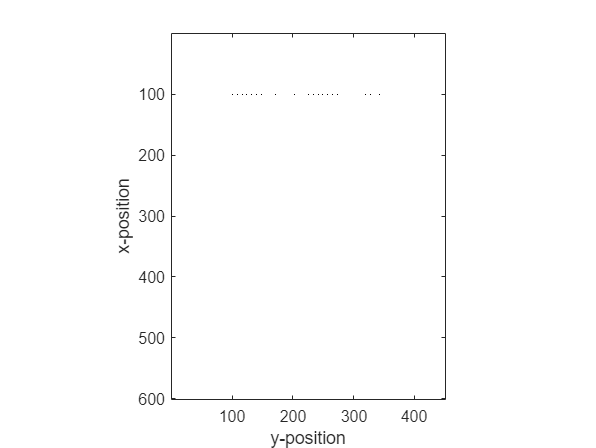


% VISUALISATION
% =========================================================================

% plot the initial pressure and sensor distribution
%positive max around 0.043-0.0449
figure;
%imagesc(Kgrid.y_vec * 1e3, Kgrid.x_vec * 1e3, source.p0 + cart2grid(Kgrid, sensor.mask), [-1, 1]);
imagesc(source.p_mask + sensor.mask, [-1, 1]);
%imagesc(source.p0 + sensor.mask, [-1, 1]);
colormap(getColorMap);
ylabel('x-position');
xlabel('y-position');
axis image;

%% 

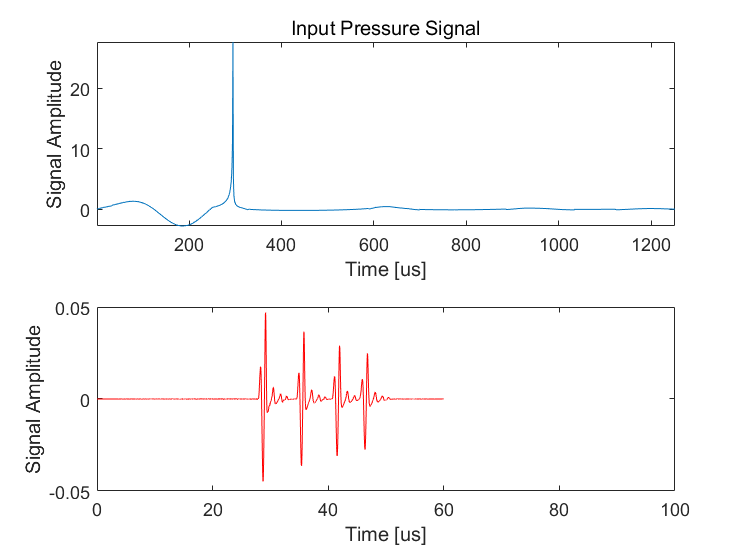


% plot the simulated sensor data
figure;
[t_sc, scale, prefix] = scaleSI(max(Kgrid.t_array));

subplot(2, 1, 1);
plot(source.p)
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([-inf,inf,-inf,inf]);
title('Input Pressure Signal');

subplot(2, 1, 2);
plot(Kgrid.t_array * scale, sensor_data(32,:), 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([0,100,-0.05,0.05]);

%axis tight;
%axis([0,10.5,-inf,inf]);



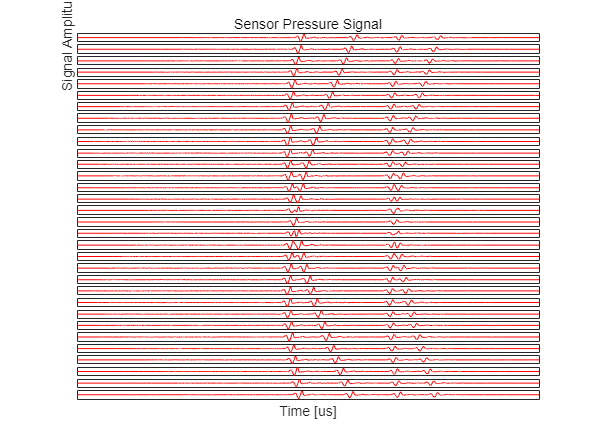

%plot all the 32 original sensor signal 
figure
for i = 1:32
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data(i,:), 'r-');

    %axis([0,10.5,-inf,inf]);
    set(gca,'XTick',[],'YTick',[]);
    if i == 1
            %xlabel(['Time [' prefix 's]']);
            ylabel('Signal Amplitude');
            title('Sensor Pressure Signal');
    end
    if i == 32 
        xlabel(['Time [' prefix 's]']);
        %ylabel('Signal Amplitude');
        %title('Sensor Pressure Signal');
    end

end

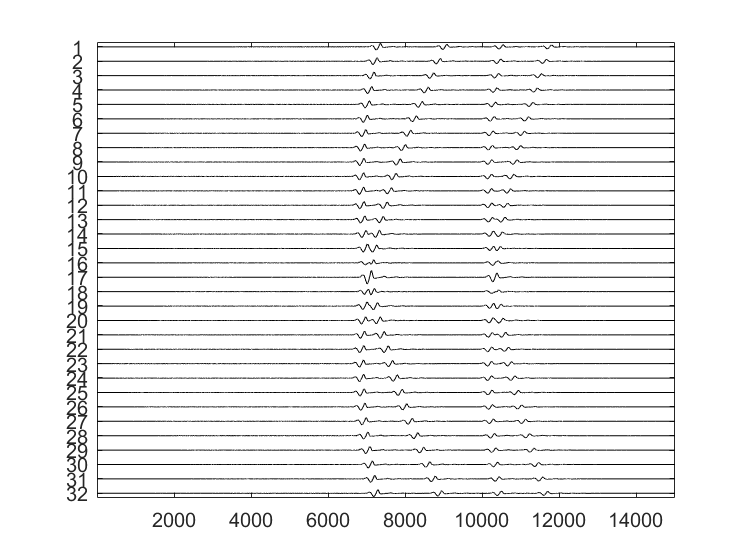


figure
stackedPlot(sensor_data)

%% dt=40ns tend=100.04us timestep = 2502 totalt=1e-4
% Kgrid.t_array
% t_array_limit = 1/source_freq*5
% t_array_new = Kgrid.t_array(1:32)
% 1/2E-4
% 128*1.414/1500


%obtian all the sensor position
sensorpoistion = zeros(1,32)

sensorpoistion =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j=1

j = 1

for i = 1:450
    if sensor.mask(100,i)==1
        
        sensorpoistion(j) = i;
        j = j+1;
    end
end
sensorpoistion()

ans =    101   109   117   124   132   140   148   156   164   171   179   187   195   203   210   218   226   234   242   249   257   265   273   281   289   296   304   312   320   328   335   343



%all the source position

%Create a 20mm times 20mm grid, which is 200 times 200
map_length = zeros(1,200);
map_width = zeros(1,200);
%x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2

for i = 1:200
    map_length(i)=350-Nx/6+i;
    map_width(i)=225-20/90*Ny+i;
end
map_length

map_length =    251   252   253   254   255   256   257   258   259   260   261   262   263   264   265   266   267   268   269   270   271   272   273   274   275   276   277   278   279   280   281   282   283   284   285   286   287   288   289   290   291   292   293   294   295   296   297   298   299   300


map_width

map_width =    126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150   151   152   153   154   155   156   157   158   159   160   161   162   163   164   165   166   167   168   169   170   171   172   173   174   175


%x = 350-map_width:350+map_width
%y = 225-map_width:225+map_width


%the intensity map position
%map_width = 40/120*Nx;
%map = zeros(map_width,map_width);
timespan = length(Kgrid.t_array);
tlength = 1000;

%store the map postion
step = zeros(1,32)

step =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sensor_data_test = zeros(32,timespan);
sensor_data_new = zeros(32,timespan);
coeff = 4/32*pi;


distance_map = zeros(1,32);

%define the energy map
energymap = zeros(200,200)

energymap =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

%tof = zeros(,32);
sensorpoistion;
sensor_timewindow = zeros(32,tlength);
% for m = 1
%      for n = 1:200
%          A = zeros(32,tlength);
%         for i = 1:32
%             tof = zeros(32,1);
%             calculate distance and time of flight from each point
%             distance_map(:,i)=sqrt((sensorpoistion(i)-map_width(m))^2+(map_length(n)-100)^2);
%             tof(i) = distance_map(i)*dx/c;
%             timemin = floor(tof(i,:)/4e-9);
%             timemax = timemin+tlength-1;
%             if timemax>timespan
%                 timemax = timespan;
%             end
%             sensor_timewindow(i,:) = sensor_data(i,timemin:timemax);
%             sensor_data_sum = sum(sensor_timewindow)/32;
%             A(i,:) = distance_map(i)*sensor_timewindow(i,:);
%         end
%         sum 32 sensor data together
%         sum_A = sum(A);
%         intensity = coeff * sum_A;
% 
%         integral'
%         intensity_2 = intensity.^2;
%         Q = trapz(intensity_2);
%         coeff2 = 1/(4*pi*1500);
%         energymap(n,m)= intensity_2*intensity_2'/32/32*coeff2;
%         energymap(n,m)= Q*coeff2;
%      end
% end

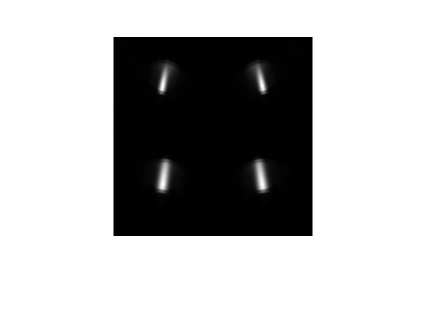


for m = 1:200
     for n = 1:200
         A = zeros(32,tlength);
        for i = 1:32
            tof = zeros(32,1);
            %calculate distance and time of flight from each point
            distance_map(:,i)=sqrt((sensorpoistion(i)-map_width(m))^2+(map_length(n)-100)^2);
            tof(i) = distance_map(i)*dx/c;
            timemin = floor(tof(i,:)/4e-9);
            timemax = timemin+tlength-1;
            if timemax>timespan
                timemax = timespan;
            end
            sensor_timewindow(i,:) = sensor_data(i,timemin:timemax);
            %sensor_data_sum = sum(sensor_timewindow)/32;
            A(i,:) = distance_map(i)*sensor_timewindow(i,:);
        end
        %sum 32 sensor data together
        sum_A = sum(A);
        intensity = coeff * sum_A;

        %integral'
        intensity_2 = intensity.^2;
        Q = trapz(intensity_2);
        coeff2 = 1/(4*pi*1500);
%         energymap(n,m)= intensity_2*intensity_2'/32/32*coeff2;
        energymap(n,m)= Q*coeff2;
     end
end

figure
imshow(energymap,[])

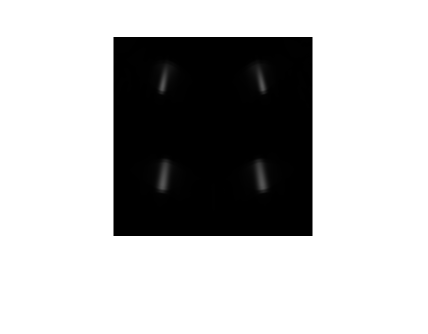

figure

%imshow(energymap/256)

imshow(uint8(energymap))

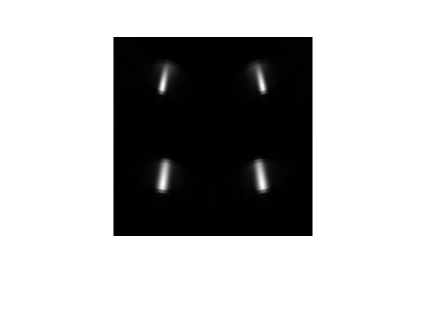

rea = im2uint8(mat2gray(energymap));
figure
imshow(rea)


% step
% timeshift
% distance_map
% for m = 1:200
%     for n = 1:200
%         i
%         for i = 1:32
%             %calculate distance from each point
%             distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(n))^2+(map_length(m)-100)^2);
%             timeshift = distance_map*dx/c;
% 
%             
%             %apply the time delay to the sensor data
% %             step(i) = floor(tj(i)/4e-8);
% %             sensor_data_test(i,:) = sensor_data(i,:);
% %             sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));

%         end
%     end
% end

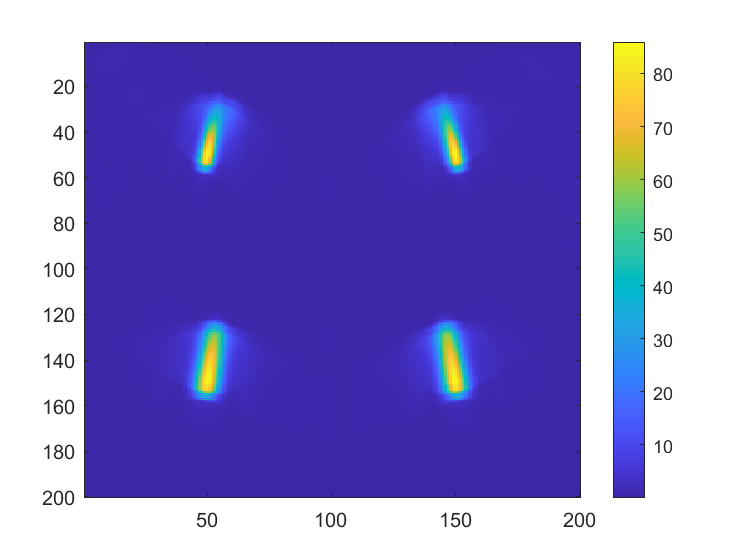


figure

%imshow(energymap/256)

%imshow(uint8(energymap))
imagesc(energymap);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例

%source strength = 4pi/N*sum(distance*signal)

coeff = 4/32*pi

coeff = 0.3927

%distance_total = sum(distance, 'all')


%Shift test
%1st calculate how much time step to move
% step = tj(1)/4e-8%how many step to move
% step = floor(step)
% sensor_data_test = sensor_data(1,:)
% sensor_data_new = circshift(sensor_data_test, -step)

%shift test2
% function [AfterArray] = ArrayDisplacement(BeforeArray,direction,len,type)
% ArrayEnd = length(BeforeArray);
% eforeArrayL = BeforeArray(1:len);
% BeforeArrayR = BeforeArray(len+1:ArrayEnd);
% BeforeArrayL = fliplr(BeforeArrayL);
% BeforeArrayR = fliplr(BeforeArrayR);
% BeforeArray = [BeforeArrayL BeforeArrayR];
% AfterArray = fliplr(BeforeArray);

%apply the time delay to the sensor data
step = zeros(1,32)

step =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sensor_data_test = zeros(32,1501);
sensor_data_new = zeros(32,1501);
tj = distance*dx/c;

警告: 函数 sum 与某个 MATLAB 内置函数同名。建议您重命名该函数以避免潜在的名称冲突。


警告: 函数 sum 与某个 MATLAB 内置函数同名。建议您重命名该函数以避免潜在的名称冲突。


'distance' 需要以下项之一:
  Antenna Toolbox
  Communications Toolbox
  Automated Driving Toolbox
  Sensor Fusion and Tracking Toolbox
  Mapping Toolbox
  Navigation Toolbox
  

for i = 1:32
    step(i) = floor(tj(i)/4e-8);
    sensor_data_test(i,:) = sensor_data(i,:);
    sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
    %plot the shifted data 
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data_new(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
    %axis([0,10.5,-inf,inf]);
end



figure

stackedPlot(Kgrid.t_array,sensor_data)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

figure
stackedPlot(Kgrid.t_array,sensor_data_new)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');


%calculate intensity
figure
A = zeros(32,1501)
A(1,:) = distance(1)*sensor_data_new(1,:);
for i = 1:32
    A(i,:) = distance(i)*sensor_data_new(i,:);
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, A(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
end
figure
sum_A = sum(A)

%plot(Kgrid.t_array * scale, sum_A, 'r-');
intensity = coeff * sum_A
plot(Kgrid.t_array * scale, intensity, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Source strength');


%integral'
intensity_2 = intensity.^2;
Q = trapz(intensity_2)
coeff2 = 1/(4*pi*1500)
%fun = @(x) exp(-x.^2).*log(x).^2;
fun = @(x) (coeff2*sum(A)).^2
%fun_2 = fun.^2
q = integral(fun,0,5e-05,'ArrayValued',true)
figure
plot(Kgrid.t_array * scale, q, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Energy');



%original received signal
step(1)
%sensor_data_new(1,:) = circshift(sensor_data_test(1,:), -step);
figure
subplot(2,1,1);
plot(Kgrid.t_array * scale, sensor_data_test(1,:), 'r-');
set(gca,'XTick',[],'YTick',[]);
xlabel(['Time [' prefix 's]']);
%shifted signal
subplot(2,1,2);
plot(Kgrid.t_array * scale, sensor_data_new(1,:), 'r-');
xlabel(['Time [' prefix 's]']);

% sensor_data_new = distance * sensor_data
% figure
% subplot(2,1,1);
% plot(Kgrid.t_array * scale, sensor_data_new, 'r-');
% subplot(2,1,2);
% plot(Kgrid.t_array * scale, sensor_data(31,:), 'r-');


help kWaveGrid


